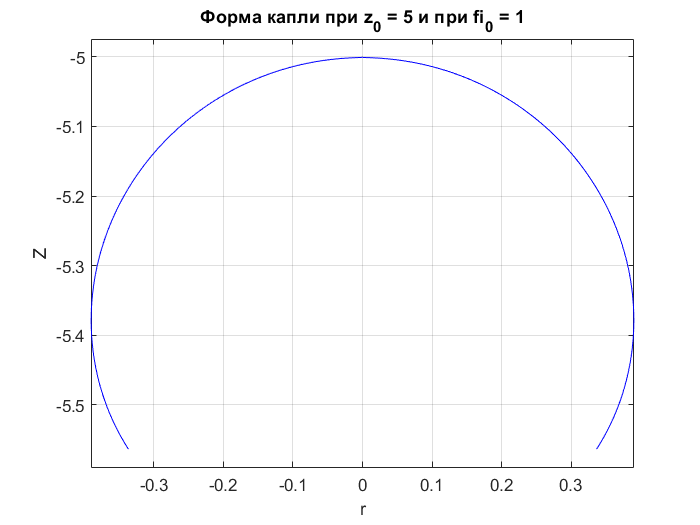

clear
clc
close all
a = 0.39;
z0 = 5;
fi0 = 1;
fi(1) = fi0;
r(1) = 0;
Z(1) = -z0;
h = 0.001;
s(1) = 0;
i=1;
Y = [fi; r; Z];
K1 = [0, 0, 0];
K2 = [0, 0, 0];
while Y(1, i) <= pi - fi0
    K1 = F(s(i), Y(:, i), z0, a);
    K2 = F(s(i)+h, Y(:, i)+h*K1, z0, a);
    Y(:, i+1) = Y(:, i) + h*(0.5*K1+0.5*K2);
    s(i+1) = s(i)+h;
    i = i+1;
end

plot(-Y(2, :), Y(3, :), 'b', Y(2, :), Y(3, :), 'b')
xlabel("r")
ylabel("Z")
grid on
title(['Форма капли при z_0 = ', num2str(z0), ' и при fi_0 = ', num2str(fi0)])
axis equal

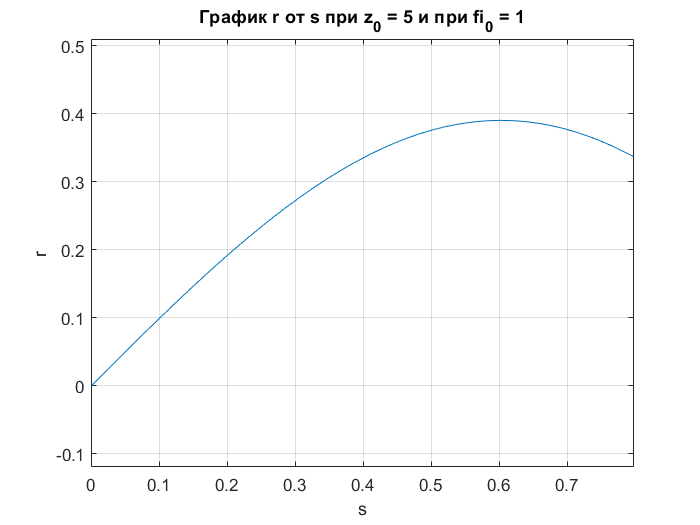


plot(s, Y(2, :))
xlabel("s")
ylabel("r")
grid on
axis equal
title(['График r от s при z_0 = ', num2str(z0), ' и при fi_0 = ', num2str(fi0)])

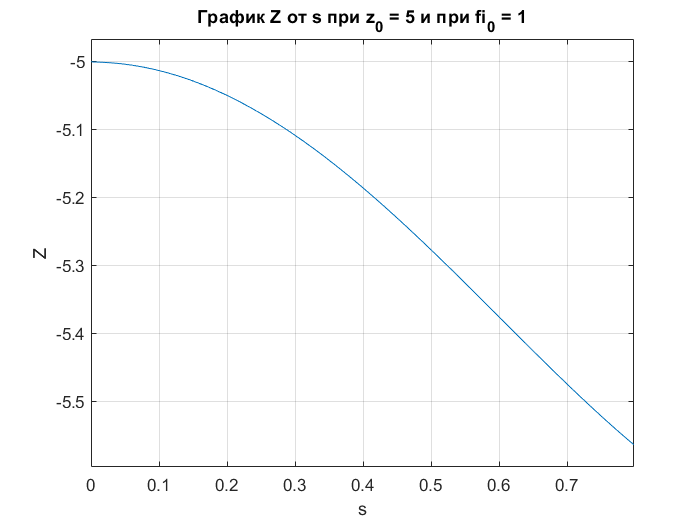


plot(s, Y(3, :))
xlabel("s")
ylabel("Z")
grid on
axis equal
title(['График Z от s при z_0 = ', num2str(z0), ' и при fi_0 = ', num2str(fi0)])

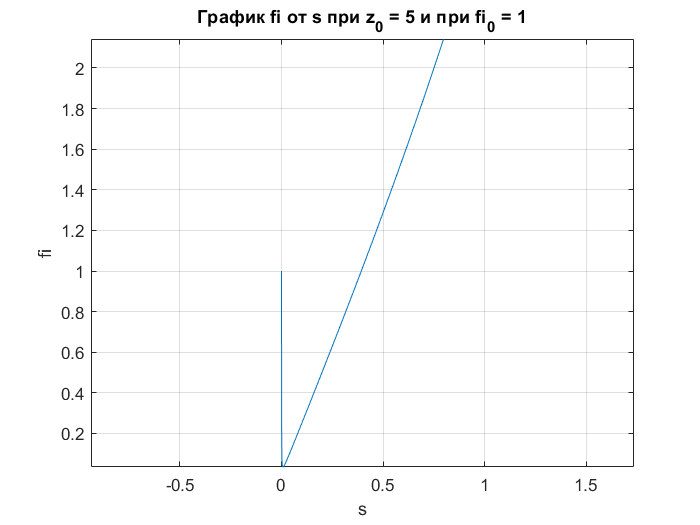


plot(s, Y(1, :))
xlabel("s")
ylabel("fi")
grid on
axis equal
title(['График fi от s при z_0 = ', num2str(z0), ' и при fi_0 = ', num2str(fi0)])

function X = F(s, Y, z0, a)
    if s == 0
        X = [(-z0/(2*a*a)-Y(3)/a*a); cos(Y(1)); -sin(Y(1))];
    else
        X = [(-(sin(Y(1))/Y(2))-Y(3)/a*a); cos(Y(1)); -sin(Y(1))];
    end
end
